clear all
syms x1(t) x2(t) y1(t) y2(t) theta1(t) theta2(t) F1x(t) F1y(t) F2x(t) F2y(t) F3x(t) F3y(t) m1 m2 L h1(t) h2(t) g



IG1=1/12*m1*L^2; IG2=1/12*m2*L^2;

rG1=[x1(t);y1(t)];
rG2=[x2(t);y2(t)];
F1=[F1x(t);F1y(t)];
F2=[F2x(t);F2y(t)];
F3=[F3x(t);F3y(t)];

%Forces 1 and 2 act on the top arm, Force 3 on the bottom arm. 

%F=ma for top arm
eq1=m1*diff(rG1,t,t)==F1+F2-m1*g*[0;1];
MF1G1=cross(-[rG1;0],[F1;0]);
MF2G1=cross([rG1;0],[F2;0]);
%IG theta''=M for the top arm
eq2=IG1*diff(theta1(t),t,t)==MF1G1(3)+MF2G1(3)+h1(t); % <-- forcing term 1 here. 

%F=ma for the bottom arm.
eq3=m2*diff(rG2,t,t)==F3-m2*g*[0;1];
%IG theta''=M for the bototm.
MF3G2=cross(L/2*[-sin(theta2(t));cos(theta2(t));0],[F3;0]) ;  
eq4=IG2*diff(theta2(t),t,t)==MF3G2(3)+ h2(t);% <-- forcing 2 here.

%Keep top arm anchored at origin. 
eq5=rG1+L/2*[-sin(theta1(t));cos(theta1(t))]==[0;0];
%Keep top arm and bottom arm attached. 
eq6=rG1+L/2*[sin(theta1(t));-cos(theta1(t))]==rG2+L/2*[-sin(theta2(t));cos(theta2(t))];
%F2 and F3 must be related. 
eq7=F2==-F3;


%As usual, set up equations of motion.  NOTICE THE CONSTITUATIVE RELATION
%F2==-F3 goes in the DEs!  This is because that equation doesn't need to be
%differentiated.  Maybe we should do something about that for clarity?

DES=[eq1;eq2;eq3;eq4;eq7];
PositionConstraints=[eq5;eq6];


%Now get general governing equations.  Note that we have to say that h1, h2
%are paramters. 

%Or, get a general formulation and then timestep. 
[governingDEs,PPs]=generateGoveringDEs(DES,PositionConstraints,[],[theta1,diff(theta1),theta2,diff(theta2)],[h1;h2])

The unknown functions are:
F1x(force)
F2x(force)
F3x(force)
F1y(force)
F2y(force)
F3y(force)
theta1
theta2
x1
x2
y1
y2

Expected Number of State Variables:4


%Substitute in specific paramters. 
paramVals.m1=4; paramVals.m2=2; paramVals.L=3; paramVals.g=9.81; paramVals.h1=cos(4*t); paramVals.h2=4*sin(3*t);
specificDEs=subs(governingDEs,paramVals);
specificPPs=subs(PPs,paramVals);
soln=timeStepODESystem(specificDEs,[0,30],{theta1==0, diff(theta1)==0,theta2==0,diff(theta2)==0},specificPPs,0);

The unknown functions (just the base functions, not derivatives) are: theta1(t),theta2(t)


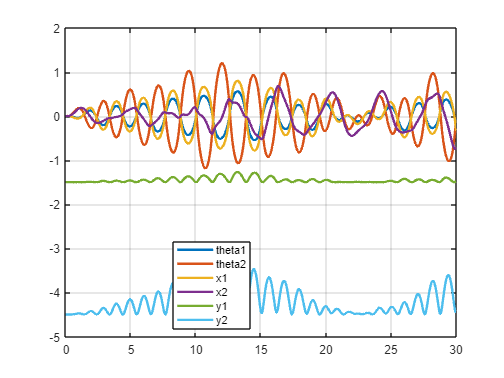

plot(soln.t,soln.theta1,soln.t,soln.theta2,soln.t,soln.x1,soln.t,soln.x2,soln.t,soln.y1,soln.t,soln.y2,'LineWidth',2); grid on; legend({"theta1","theta2","x1","x2","y1","y2"},'Location',"best");

%How much energy had we added to the system at each time?
%Good question for later. 

